% Known Position found using google maps. Converted
% to northing and easting using utm function in python3 terminal

%**********************************************************************************
% data from stationary open spot
bag_staticOpen = rosbag("2023-02-06-01-08-03.bag")

bag_staticOpen =   BagSelection with properties:

           FilePath: '/MATLAB Drive/2023-02-06-01-08-03.bag'
          StartTime: 1.675663684057189e+09
            EndTime: 1.675664310070284e+09
        NumMessages: 627
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [627×4 table]


bSel = select(bag_staticOpen, 'Topic', '/gps')

bSel =   BagSelection with properties:

           FilePath: '/MATLAB Drive/2023-02-06-01-08-03.bag'
          StartTime: 1.675663684057189e+09
            EndTime: 1.675664310070284e+09
        NumMessages: 627
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [627×4 table]


msgStructsOpen = readMessages(bSel,"DataFormat","struct")

msgStructsOpen = 627×1 cell array
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}


NorthingOpen = cellfun(@(m) double(m.UTMNorthing),msgStructsOpen)

NorthingOpen = 1.0e+06 *

   4.689324500000000
   4.689324500000000
   4.689324500000000
   4.689324500000000
   4.689324500000000
   4.689324500000000
   4.689324500000000
   4.689324500000000
   4.689324500000000
   4.689324500000000


EastingOpen = cellfun(@(m) double(m.UTMEasting),msgStructsOpen)

EastingOpen = 1.0e+05 *

   3.277827812500000
   3.277827500000000
   3.277827812500000
   3.277827812500000
   3.277828437500000
   3.277828750000000
   3.277829062500000
   3.277828750000000
   3.277828125000000
   3.277827187500000



NorthingOpenEnd = NorthingOpen(length(NorthingOpen))

NorthingOpenEnd =      4689328


EastingOpenEnd = EastingOpen(length(EastingOpen))

EastingOpenEnd =      3.277833437500000e+05



% open spot's longitude, North (positive)
known_long_dec_openspot = 42.33725

known_long_dec_openspot =   42.337249999999997


% open spot's latitude, West (negative)
known_lat_dec_openspot = -71.09053

known_lat_dec_openspot =  -71.090530000000001


known_open_easting = 327780.8534146161

known_open_easting =      3.277808534146161e+05


known_open_northing = 4689338.318667219

known_open_northing =      4.689338318667219e+06


%applying correction (subtracting first values)

%NorthingOpenEndCorrected = NorthingOpenEnd - NorthingOpen(1)
%EastingOpenEndCorrected = EastingOpenEnd - EastingOpen(1)

%known_open_easting_corrected = known_open_easting - EastingOpen(1)
%known_open_northing_corrected = known_open_northing - NorthingOpen(1)
NorthingOpenScaled = NorthingOpen - NorthingOpen(1)

NorthingOpenScaled =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


EastingOpenScaled = EastingOpen - EastingOpen(1)

EastingOpenScaled =                    0
  -0.031250000000000
                   0
                   0
   0.062500000000000
   0.093750000000000
   0.125000000000000
   0.093750000000000
   0.031250000000000
  -0.062500000000000



%******************************************************************************
% data from stationary occluded spot
bag_staticOccluded = rosbag("2023-02-06-03-14-31.bag")

bag_staticOccluded =   BagSelection with properties:

           FilePath: '/MATLAB Drive/2023-02-06-03-14-31.bag'
          StartTime: 1.675671272098852e+09
            EndTime: 1.675671593073539e+09
        NumMessages: 322
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [322×4 table]


bSelOccluded = select(bag_staticOccluded, 'Topic', '/gps')

bSelOccluded =   BagSelection with properties:

           FilePath: '/MATLAB Drive/2023-02-06-03-14-31.bag'
          StartTime: 1.675671272098852e+09
            EndTime: 1.675671593073539e+09
        NumMessages: 322
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [322×4 table]


msgStructsOccluded = readMessages(bSelOccluded,"DataFormat","struct")

msgStructsOccluded = 322×1 cell array
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}


NorthingOccluded = cellfun(@(m) double(m.UTMNorthing),msgStructsOccluded)

NorthingOccluded = 1.0e+06 *

   4.689326500000000
   4.689326500000000
   4.689326500000000
   4.689326500000000
   4.689326500000000
   4.689326500000000
   4.689326500000000
   4.689326500000000
   4.689326500000000
   4.689326500000000


EastingOccluded = cellfun(@(m) double(m.UTMEasting),msgStructsOccluded)

EastingOccluded = 1.0e+05 *

   3.277147187500000
   3.277149062500000
   3.277150000000000
   3.277151562500000
   3.277153125000000
   3.277154687500000
   3.277155625000000
   3.277156875000000
   3.277158437500000
   3.277159375000000



NorthingOccludedEnd = NorthingOccluded(length(NorthingOccluded))

NorthingOccludedEnd =      4689323


EastingOccludedEnd = EastingOccluded(length(EastingOccluded))

EastingOccludedEnd =      3.277193437500000e+05



% occluded spot's longitude, North (positive)
known_long_dec_occludedspot = 42.33703

known_long_dec_occludedspot =   42.337029999999999


% occluded spot's latitude, West (negative)
known_lat_dec_occludedspot = -71.09141

known_lat_dec_occludedspot =  -71.091409999999996


known_occluded_easting = 327707.7545992285

known_occluded_easting =      3.277077545992285e+05


known_occluded_northing = 4689315.672040844

known_occluded_northing =      4.689315672040844e+06




%applying correction/scaling (subtracting first values)

%NorthingOccludedEndCorrected = NorthingOccludedEnd - NorthingOccluded(1)
%EastingOccludedEndCorrected = EastingOccludedEnd - EastingOccluded(1)

%known_occluded_easting_corrected = known_occluded_easting - EastingOccluded(1)
%known_occluded_northing_corrected = known_occluded_northing - NorthingOccluded(1)
NorthingOccludedScaled = NorthingOccluded - NorthingOccluded(1)

NorthingOccludedScaled =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


EastingOccludedScaled = EastingOccluded - EastingOccluded(1)

EastingOccludedScaled =                    0
   0.187500000000000
   0.281250000000000
   0.437500000000000
   0.593750000000000
   0.750000000000000
   0.843750000000000
   0.968750000000000
   1.125000000000000
   1.218750000000000




%*******************************************************************************



% data from walking 200-300m

bag_dynamic = rosbag("2023-02-06-03-22-18.bag")

bag_dynamic =   BagSelection with properties:

           FilePath: '/MATLAB Drive/2023-02-06-03-22-18.bag'
          StartTime: 1.675671739079442e+09
            EndTime: 1.675671994094109e+09
        NumMessages: 256
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [256×4 table]


bSeldynamic = select(bag_dynamic, 'Topic', '/gps')

bSeldynamic =   BagSelection with properties:

           FilePath: '/MATLAB Drive/2023-02-06-03-22-18.bag'
          StartTime: 1.675671739079442e+09
            EndTime: 1.675671994094109e+09
        NumMessages: 256
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [256×4 table]


msgStructsdynamic = readMessages(bSeldynamic,"DataFormat","struct")

msgStructsdynamic = 256×1 cell array
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}


Northingdynamic = cellfun(@(m) double(m.UTMNorthing),msgStructsdynamic)

Northingdynamic = 1.0e+06 *

   4.689357000000000
   4.689357500000000
   4.689357500000000
   4.689357000000000
   4.689357000000000
   4.689356500000000
   4.689356500000000
   4.689356500000000
   4.689356500000000
   4.689356500000000


Eastingdynamic = cellfun(@(m) double(m.UTMEasting),msgStructsdynamic)

Eastingdynamic = 1.0e+05 *

   3.275933125000000
   3.275934687500000
   3.275935625000000
   3.275934687500000
   3.275936875000000
   3.275944062500000
   3.275950000000000
   3.275958437500000
   3.275969687500000
   3.275980312500000


% don't know if i need to do this correciton but...maybe?
NorthingdynamicScaled = Northingdynamic - Northingdynamic(1)

NorthingdynamicScaled =                    0
   0.500000000000000
   0.500000000000000
                   0
                   0
  -0.500000000000000
  -0.500000000000000
  -0.500000000000000
  -0.500000000000000
  -0.500000000000000


EastingdynamicScaled = Eastingdynamic - Eastingdynamic(1)

EastingdynamicScaled = 1.0e+02 *

                   0
   0.001562500000000
   0.002500000000000
   0.001562500000000
   0.003750000000000
   0.010937500000000
   0.016875000000000
   0.025312500000000
   0.036562500000000
   0.047187500000000


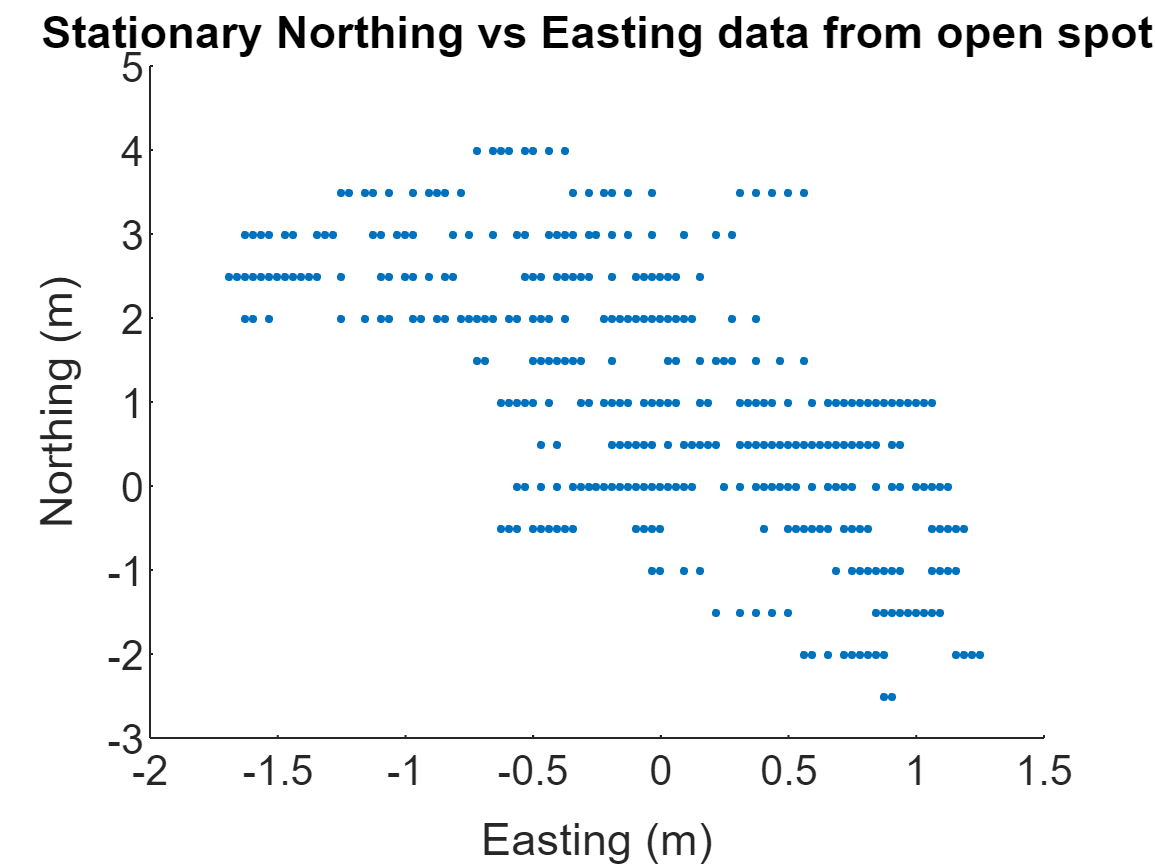



%*************************************************************************************************

% plotting the scatterplots for all three cases
figure
scatter(EastingOpenScaled, NorthingOpenScaled, '.')
title('Stationary Northing vs Easting data from open spot')
xlabel('Easting (m)')
ylabel('Northing (m)')
xlim([-2 1.5])
ylim([-3 5])

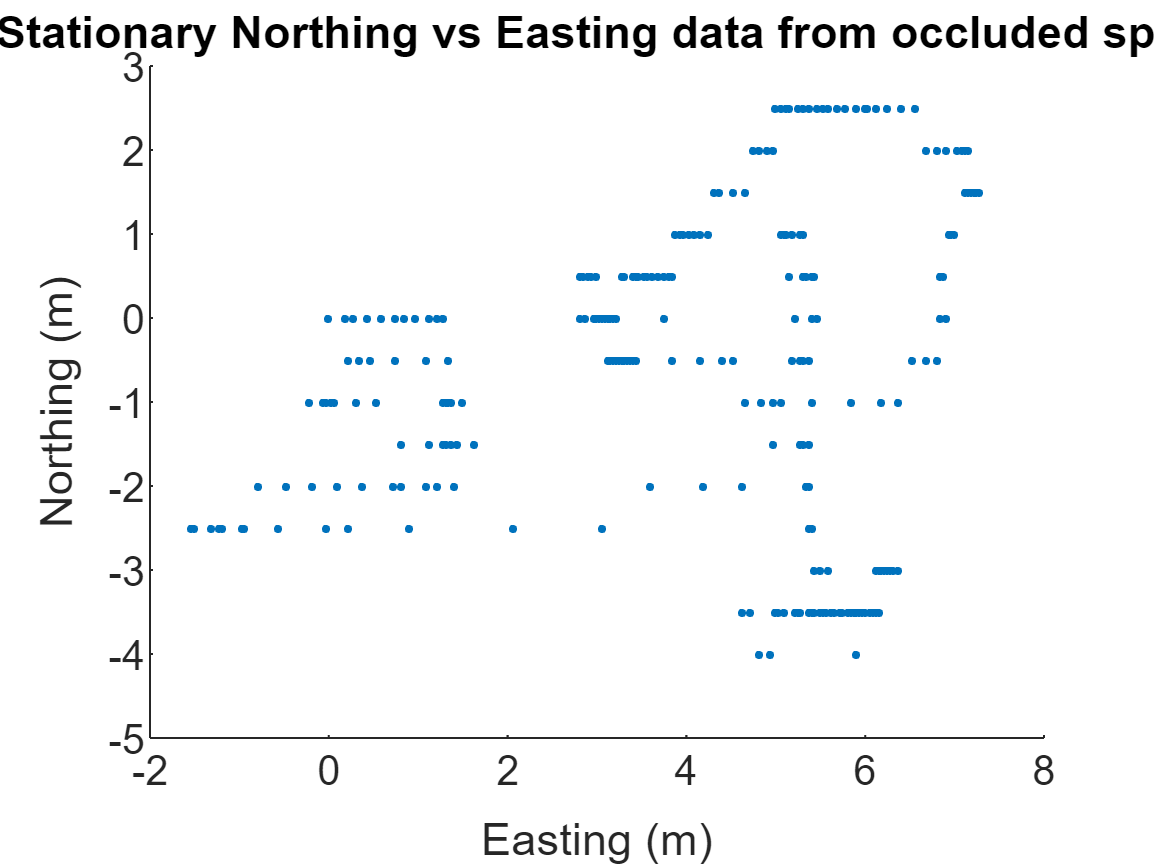



scatter(EastingOccludedScaled, NorthingOccludedScaled, '.')
title('Stationary Northing vs Easting data from occluded spot')
xlabel('Easting (m)')
ylabel('Northing (m)')
xlim([-2 8])
ylim([-5 3])







p = polyfit(EastingdynamicScaled, NorthingdynamicScaled, 1)

p =   -0.137012096959463  -2.351421002001709


f = polyval(p,EastingdynamicScaled)

f =   -2.351421002001709
  -2.372829142151625
  -2.385674026241575
  -2.372829142151625
  -2.402800538361507
  -2.501277983051122
  -2.582628915620803
  -2.698232872430351
  -2.852371481509747
  -2.997946834529177


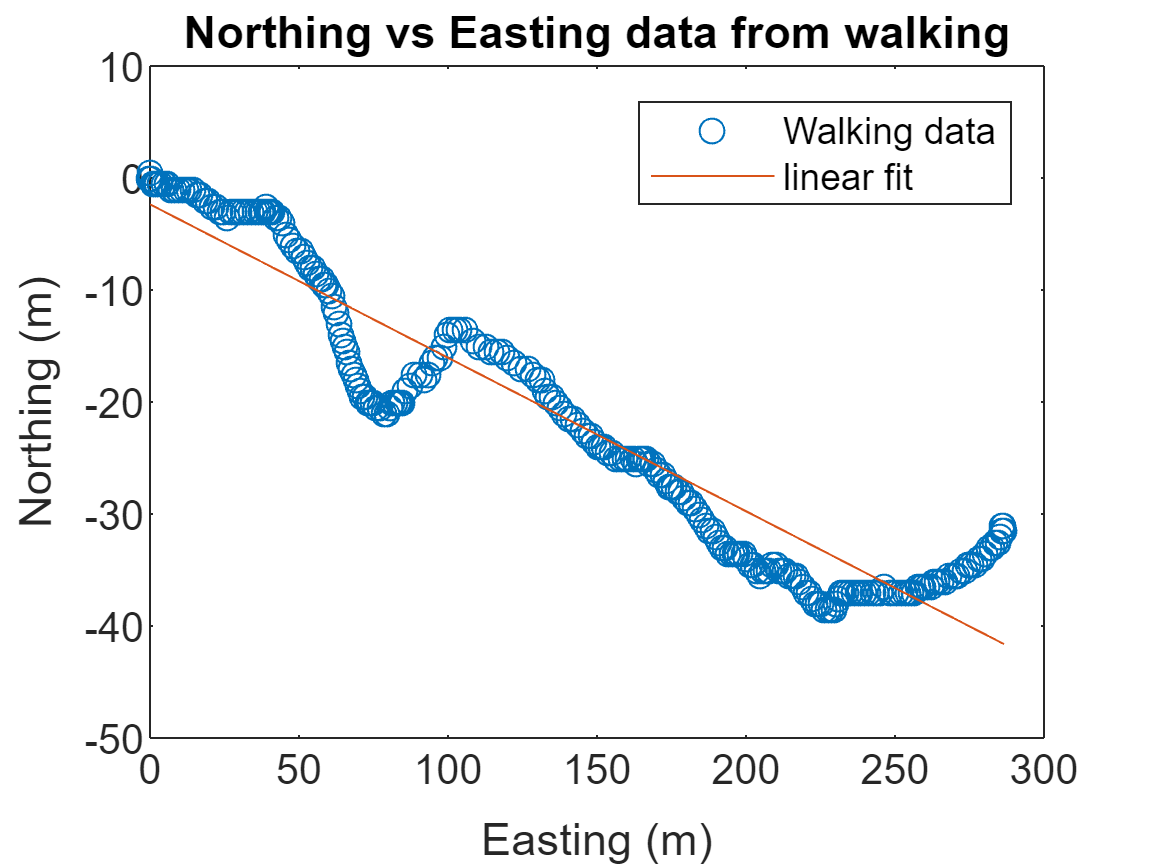

plot(EastingdynamicScaled,NorthingdynamicScaled,'o',EastingdynamicScaled,f,'-')
legend('Walking data','linear fit')
title('Northing vs Easting data from walking')
xlabel('Easting (m)')
ylabel('Northing (m)')








% making the histograms

Distances_Open = ((NorthingOpen - known_open_northing).^2 +(EastingOpen - known_open_easting).^2).^0.5

Distances_Open =   13.952494865704717
  13.948211348718573
  13.952494865704717
  13.952494865704717
  13.961267802406280
  13.965757092778793
  13.970314843391899
  13.965757092778793
  13.956847038336107
  13.943996550649556


h = histogram(Distances_Open)

h =   Histogram with properties:

             Data: [627×1 double]
           Values: [10 17 46 87 82 33 54 61 69 65 31 25 18 27 2]
          NumBins: 15
         BinEdges: [9.500000000000000 10 10.500000000000000 11 11.500000000000000 12 12.500000000000000 13 13.500000000000000 14 14.500000000000000 15 15.500000000000000 16 16.500000000000000 17]
         BinWidth: 0.500000000000000
        BinLimits: [9.500000000000000 17]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


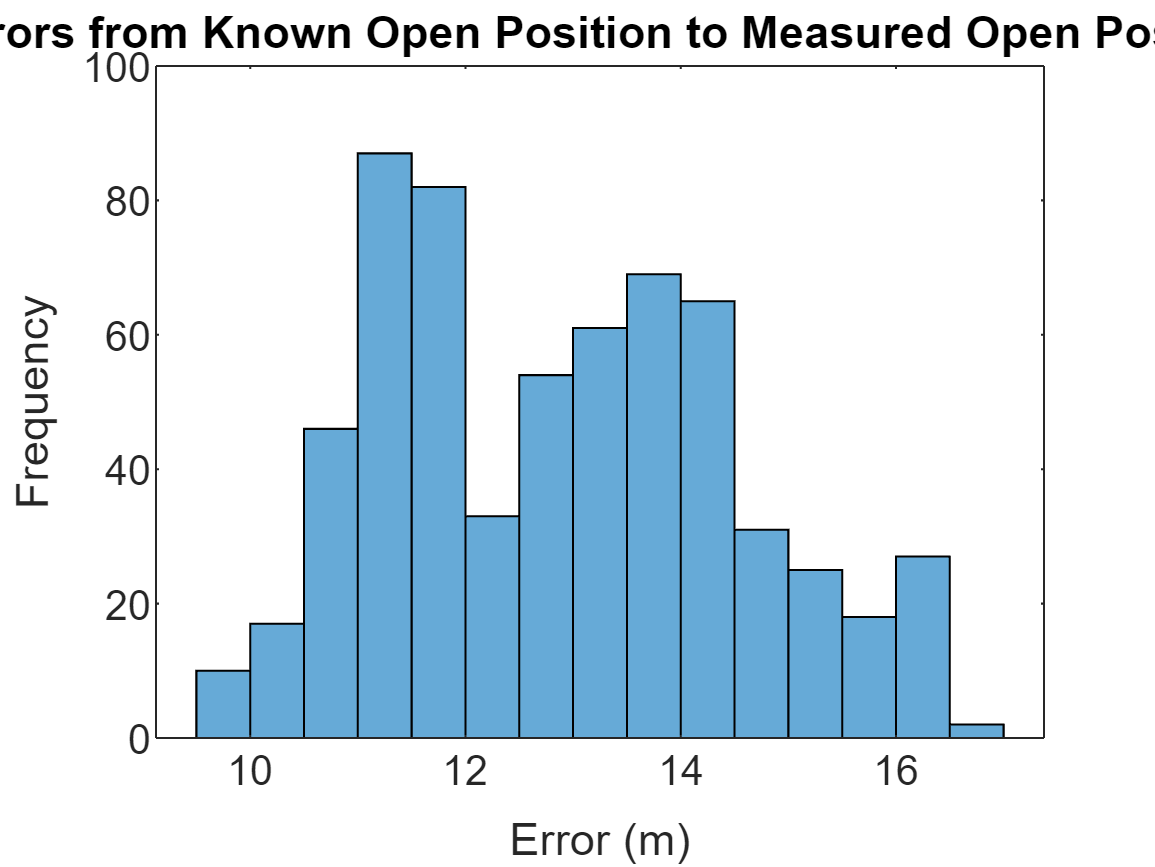

title('Errors from Known Open Position to Measured Open Postion')
xlabel('Error (m)')
ylabel('Frequency')

Error_RMS_Open = rms(Distances_Open)

Error_RMS_Open =   13.020239832562813



Distances_Occluded = ((NorthingOccluded - known_occluded_northing).^2 + (EastingOccluded - known_occluded_easting).^2).^0.5

Distances_Occluded =   12.874163873622637
  12.976548394476946
  13.028450860188951
  13.115987710422404
  13.204793203550933
  13.294841917154871
  13.349457439697474
  13.422951021558893
  13.515881757427527
  13.572198219629650


q = histogram(Distances_Occluded)

q =   Histogram with properties:

             Data: [322×1 double]
           Values: [2 11 8 32 17 111 59 33 16 30 3]
          NumBins: 11
         BinEdges: [9 10 11 12 13 14 15 16 17 18 19 20]
         BinWidth: 1
        BinLimits: [9 20]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


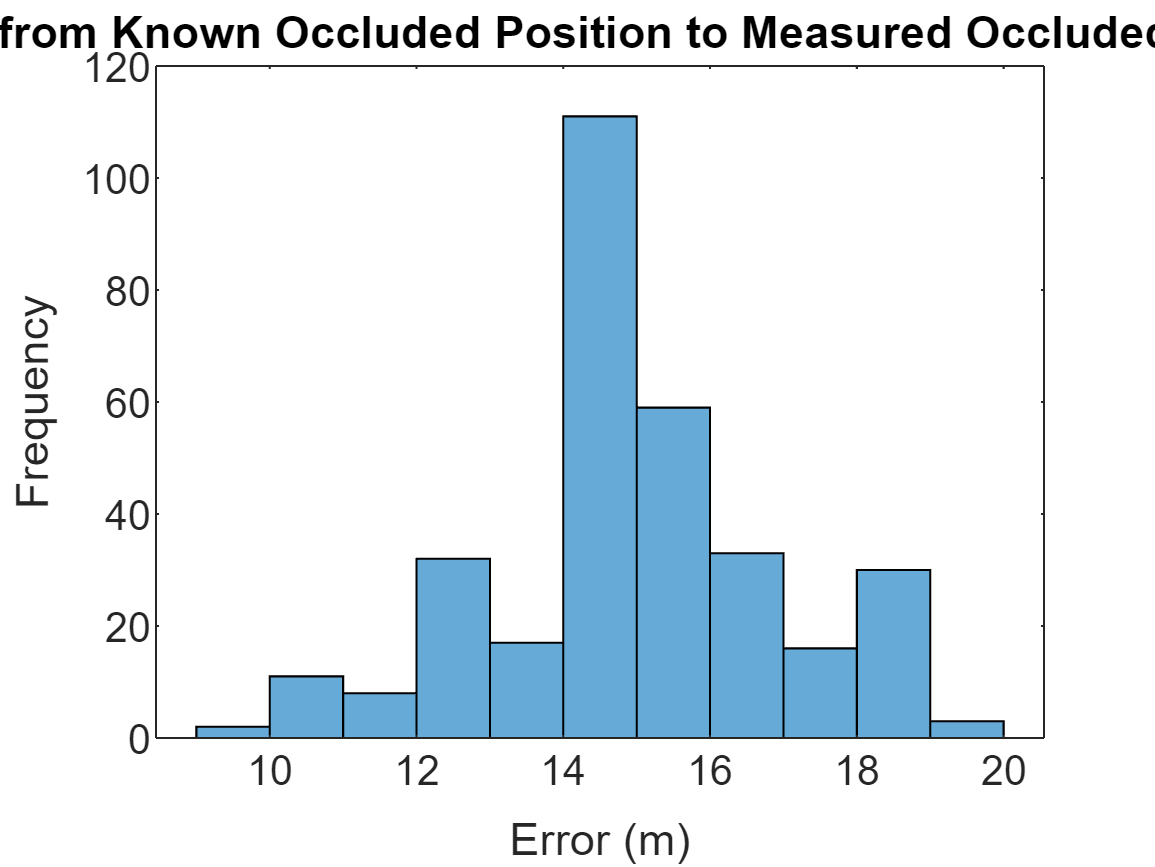

title('Errors from Known Occluded Position to Measured Occluded Postion')
xlabel('Error (m)')
ylabel('Frequency')

Error_RMS_Occluded = rms(Distances_Occluded)

Error_RMS_Occluded =   15.108200115464019











AltitudeOpen = cellfun(@(m) double(m.Altitude),msgStructsOpen)

AltitudeOpen =   11.000000000000000
  11.000000000000000
  11.100000381469727
  11.300000190734863
  11.500000000000000
  11.600000381469727
  11.699999809265137
  11.600000381469727
  11.600000381469727
  11.399999618530273


SecsOpen = cellfun(@(m) m.Header.Stamp.Sec,msgStructsOpen)

SecsOpen = 627×1 uint32 column vector
   22084
   22085
   22086
   22087
   22088
   22089
   22090
   22091
   22092
   22093


nSecsOpen = cellfun(@(m) m.Header.Stamp.Nsec,msgStructsOpen)

nSecsOpen = 627×1 uint32 column vector
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


TimeOpen = SecsOpen + (nSecsOpen*(10^-9))

TimeOpen = 627×1 uint32 column vector
   22084
   22085
   22086
   22087
   22088
   22089
   22090
   22091
   22092
   22093


TimeOpen = TimeOpen - TimeOpen(1)

TimeOpen = 627×1 uint32 column vector
   0
   1
   2
   3
   4
   5
   6
   7
   8
   9



scatter(TimeOpen, AltitudeOpen)
title("Altitude vs Time from Open Spot")
xlabel('Time (s)')
ylabel('Altitude (m)')




AltitudeOccluded = cellfun(@(m) double(m.Altitude),msgStructsOccluded)

AltitudeOccluded =    9.300000190734863
   9.500000000000000
   9.500000000000000
   9.500000000000000
   9.600000381469727
   9.500000000000000
   9.500000000000000
   9.600000381469727
   9.600000381469727
   9.600000381469727


SecsOccluded = cellfun(@(m) m.Header.Stamp.Sec,msgStructsOccluded)

SecsOccluded = 322×1 uint32 column vector
   29672
   29673
   29674
   29675
   29676
   29677
   29678
   29679
   29680
   29681


nSecsOccluded = cellfun(@(m) m.Header.Stamp.Nsec,msgStructsOccluded)

nSecsOccluded = 322×1 uint32 column vector
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


TimeOccluded = SecsOccluded + (nSecsOccluded*(10^-9))

TimeOccluded = 322×1 uint32 column vector
   29672
   29673
   29674
   29675
   29676
   29677
   29678
   29679
   29680
   29681


TimeOccluded = TimeOccluded - TimeOccluded(1)

TimeOccluded = 322×1 uint32 column vector
   0
   1
   2
   3
   4
   5
   6
   7
   8
   9


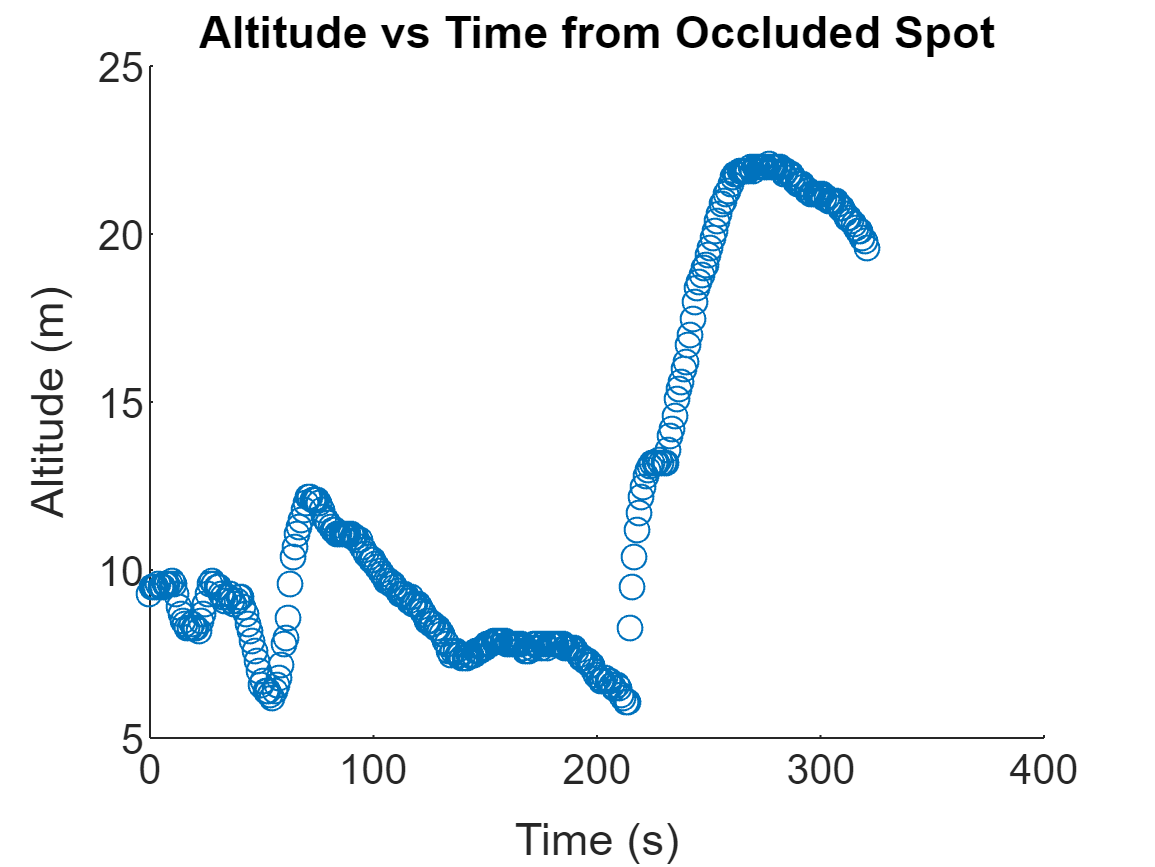

scatter(TimeOccluded, AltitudeOccluded)
title("Altitude vs Time from Occluded Spot")
xlabel('Time (s)')
ylabel('Altitude (m)')



Altitudedynamic = cellfun(@(m) double(m.Altitude),msgStructsdynamic)

Altitudedynamic =   23.299999237060547
  23.399999618530273
  23.299999237060547
  23.299999237060547
  23.200000762939453
  23.299999237060547
  23.700000762939453
  24.100000381469727
  24.500000000000000
  24.799999237060547


Secsdynamic = cellfun(@(m) m.Header.Stamp.Sec,msgStructsdynamic)

Secsdynamic = 256×1 uint32 column vector
   30139
   30140
   30141
   30142
   30143
   30144
   30145
   30146
   30147
   30148


nSecsdynamic = cellfun(@(m) m.Header.Stamp.Nsec,msgStructsdynamic)

nSecsdynamic = 256×1 uint32 column vector
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


Timedynamic = Secsdynamic + (nSecsdynamic*(10^-9))

Timedynamic = 256×1 uint32 column vector
   30139
   30140
   30141
   30142
   30143
   30144
   30145
   30146
   30147
   30148


Timedynamic = Timedynamic - Timedynamic(1)

Timedynamic = 256×1 uint32 column vector
   0
   1
   2
   3
   4
   5
   6
   7
   8
   9


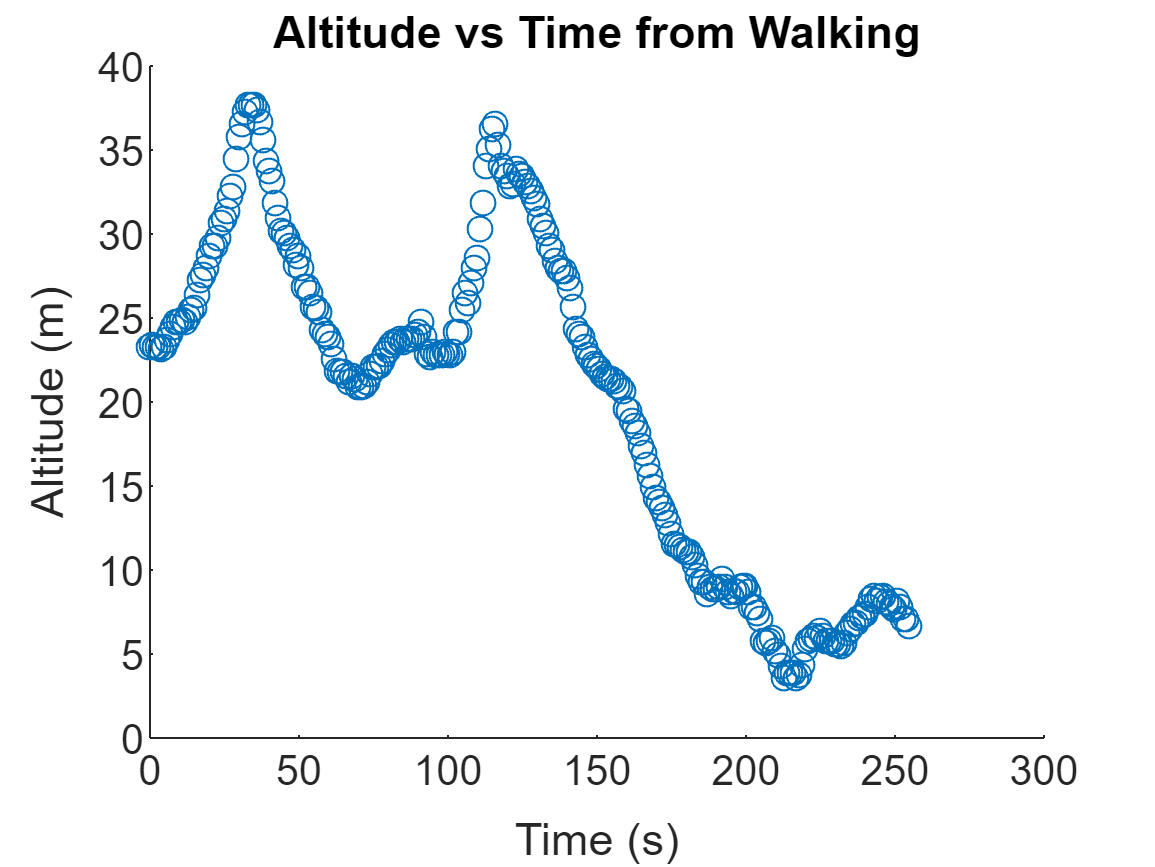

scatter(Timedynamic, Altitudedynamic)
title("Altitude vs Time from Walking")
xlabel('Time (s)')
ylabel('Altitude (m)')


HDOPavg_Open = mean(cellfun(@(m) m.HDOP,msgStructsOpen))

HDOPavg_Open = single
   1.0433793


HDOPavg_Occluded = mean(cellfun(@(m) m.HDOP,msgStructsOccluded))

HDOPavg_Occluded = single
   1.3241298
